## **Driver test program to check Clothoids library**

**Test G2 clothoid**

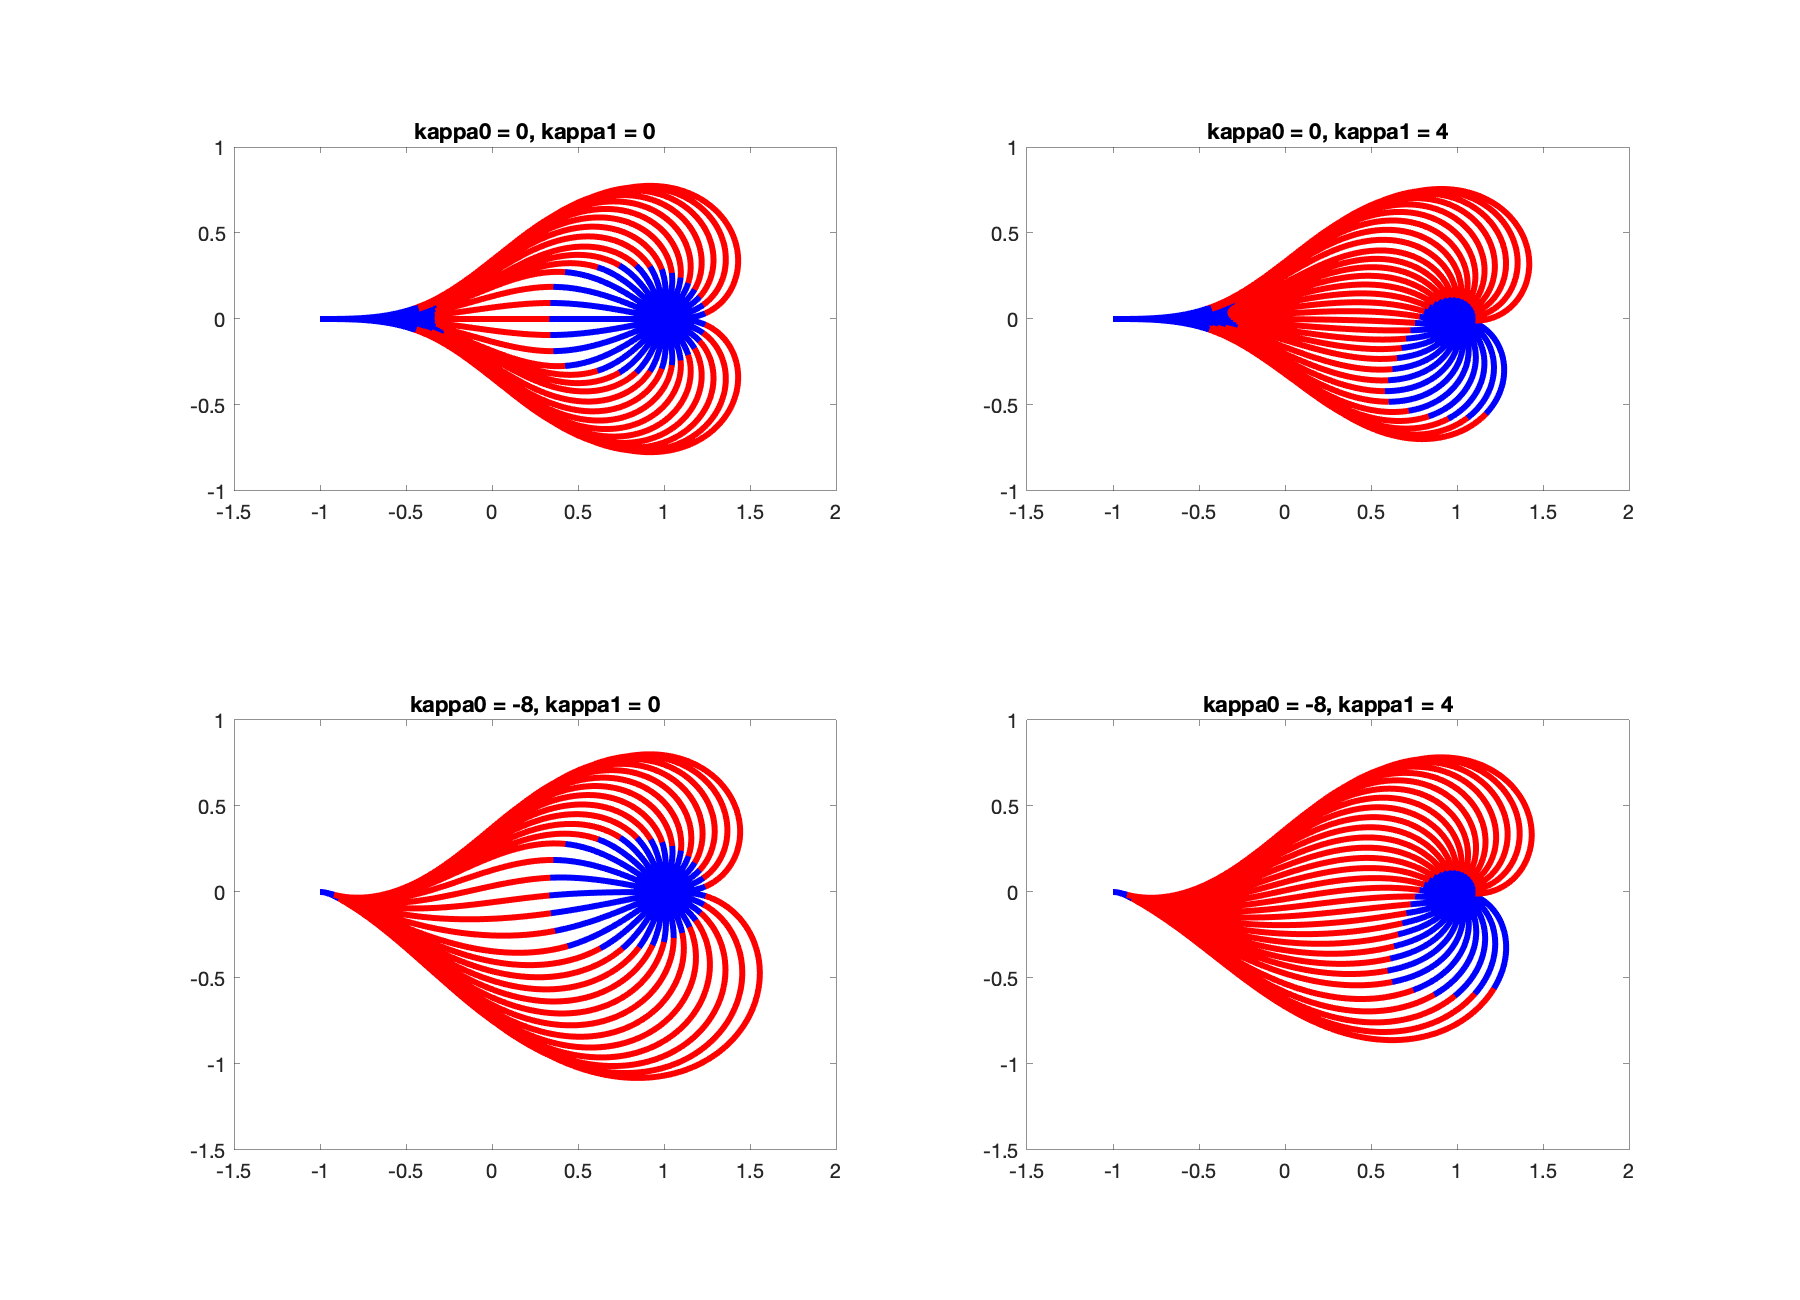

close all;

x0     = -1;
y0     = 0;
theta0 = 0;
kappa0 = [0,0,-8,-8];

x1     = 1;
y1     = 0;
kappa1 = [0,4,0,4];


close all;
figure('Position',[1,1,900,650]);

AXET = [ -1.5,2, -1,1];
AXEB = [ -1.5,2, -1.5,1];

S = ClothoidList();

for k=1:4
  subplot(2,2,k);
  %subaxis(2,2,k, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.02);
  %axis tight;
  for theta1=-pi:pi/15:pi
    iter = S.build_3arcG2(x0,y0,theta0,kappa0(k),x1,y1,theta1,kappa1(k));
    if iter < 0
      iter
    else
      S.plot();
      hold on
    end
  end
  axis equal;
  if k < 3
    axis(AXET);
  else
    axis(AXEB);
  end
  title( sprintf('kappa0 = %g, kappa1 = %g',kappa0(k),kappa1(k))); 
  if false
    set(gca,'DataAspectRatio',[1,1,1]);
    set(gca,'XTick',[-2,-1.5,-1,-0.5,0,0.5,1,1.5,2]);
    set(gca,'XTickLabel',{'$-2$','$-1.5$','$-1$','$-0.5$','$0$','$0.5$','$1$','$1.5$','$2$'});  
    set(gca,'YTick',[-2,-1.5,-1,-0.5,0,0.5,1,1.5,2]);
    set(gca,'YTickLabel',{'$-2$','$-1.5$','$-1$','$-0.5$','$0$','$0.5$','$1$','$1.5$','$2$'});
  end
end